# Riepilogo 04: coefficienti di sensibilità assoluti e relativi

## 1 - Calcolo di coefficienti di sensibilità assoluti (caso di funzioni lineari)

Sappiamo che in questo caso i coefficienti di sensibilità sono i coefficienti della combinazione lineare

% Si calcoli la matrice C dei coefficienti di sensibilità assoluti
% per i seguenti casi.
% Il vettore x indica l'ordine in cui considerare le variabili di 
% ingresso del modello della misurazione.

% 1) Vpp = V1 - V2
% x = [V1; V2]

% 2) xmedio = mean(x)
% x = vettore colonna di N = 5 grandezze in ingresso

% 3) T = a0 + a1*t + a2*t^2, con t = -1
% x = [a0; a1; a2]
% Attenzione: in questo esempio la quantità t è una costante assegnata.
% Le grandezze in ingresso sono x = [a0; a1; a2].

% 4) y = m*t + q, con m = 2, q = -1
% x = t
% Attenzione: in questo esempio le quantità m e q sono costanti assegnate.
% La grandezza in ingresso è x = t

% Dati: nessuno

% Domande:
% C1 = matrice dei coefficienti di sensibilità, caso 1
% C2 = matrice dei coefficienti di sensibilità, caso 2
% C3 = matrice dei coefficienti relativi di sensibilità, caso 3
% C4 = matrice dei coefficienti relativi di sensibilità, caso 4

% Codice iniziale
clear
N = 5;
t = -2;
m = 1.5; q = -0.5;

### Soluzione

I coefficienti di sensibilità sono semplicemente i coefficienti delle grandezze in ingresso, trattandosi di funzioni lineari.

Si noti che le matrici sono vettori riga (una sola grandezza in uscita).

% 1) Vpp = V1 - V2
% x = [V1; V2]
C1 = [1, -1] % quindi l'errore in uscita è la differenza degli errori in ingresso

C1 =      1    -1


% 2) xmedio = mean(x)
% x = vettore colonna di N = 5 grandezze in ingresso
C2 = [1, 1, 1, 1, 1]/5 % riga con elementi tutti uguali a 1/N

C2 =     0.2000    0.2000    0.2000    0.2000    0.2000


% quindi l'errore in uscita è la media degli errori in ingresso

N = 5;
C2 = 1/N*ones(1,N) % alternativa

C2 =     0.2000    0.2000    0.2000    0.2000    0.2000


% 3) T = a0 + a1*t + a2*t^2, con t = -1
% x = [a0; a1; a2]
C3 = [1, -1, 1] % con calcoli a mente

C3 =      1    -1     1


t = -1; 
C3 = [1, t, t^2] % alternativa

C3 =      1    -1     1


% 4) y = m*t + q, con m = 2, q = -1
% x = t
C4 = 2 % valore di m

C4 = 2

## 2 - Calcolo di coefficienti di sensibilità relativi da coefficienti assoluti

Questo esercizio illustra la semplice formula per passare da $C$ a $C_r$, senza dover calcolare $C_r$ con le derivate logaritmiche.

Questo è un caso in cui è molto facile scrivere la matrice $C$, ed è quindi naturale calcolare $C_r$ utilizzando la formula per passare da $C$ a $C_r$.

Naturalmente è possibile calcolare $C_r$ anche eseguendo le derivate.

% Da Vmax e Vmin si misurano:
% - la tensione picco-picco Vpp
% - la media delle tensioni Vmedia

% Dati
% Vmax = tensione massima
% Vmin = tensione minima

% Domande
% x = vettore colonna delle grandezze in ingresso Vmax, Vmin
% theta = vettore colonna delle grandezze in uscita Vpp, Vmedia
% C = matrice dei coefficienti di sensibilità assoluti
% Cr = matrice dei coefficienti di sensibilità relativi

% Codice iniziale
clear
Vmax = 100.1;
Vmin = 100;

### Soluzione

x = [Vmax; Vmin] % vettore colonna

x =   100.1000
  100.0000


Vpp = Vmax - Vmin; % modello della misurazione
Vmedia = (Vmax + Vmin)/2; % modello della misurazione

theta = [Vpp; Vmedia] % vettore colonna

theta =     0.1000
  100.0500


C = [1, -1; 1/2, 1/2] % si scrive per ispezione

C =     1.0000   -1.0000
    0.5000    0.5000


Cr = 1.0e+03 *

    1.0010   -1.0000
    0.0005    0.0005


Si ricordi che la relazione tra $C_r$ e $C$, in forma scalare, è:


$$C_{r,i\;n} =C_{i\;n} \;\frac{x_n }{\theta_i }$$



$$C_r \left(i,n\right)=C\left(i,n\right)\;\frac{x\left(n\right)}{\theta \;\left(i\right)}$$


Quindi:

- la moltiplicazione per $x\;$ riguarda le colonne di C e Cr 

- la divisione per $\theta$ riguarda le righe di C e Cr

Nella formula matriciale:

- theta deve essere un vettore colonna: in questo modo la divisione è applicata alle righe di C

- x deve essere un vettore riga (quindi x'): in questo modo la moltiplicazione è applicata alle colonne di C

Conclusione:

Cr = C./theta.*x' % formula per passare direttamente da C a Cr

*Nota "culturale" sull'incertezza relativa in una differenza di misure*

Cr(1,:) % coefficienti relativi di sensibilità di Vpp
Cr(2,:) % coefficienti relativi di sensibilità di Vmedia

Cr = 1.0e+03 *

    1.0010   -1.0000
    0.0005    0.0005


In questo esempio, i coefficienti relativi della misura Vpp = Vmax - Vmin sono pari a circa 1000, -1000. Quindi l'incertezza relativa in ingresso è moltiplicata per 1000 volte. 

Questa è una conseguenza del fatto che *Vmax e Vmin sono molto grandi rispetto alla loro differenza Vpp*.

Misurare una quantità come differenza "piccola" di quantità "grandi" è un'operazione sconsigliabile, perché di solito l'incertezza relativa finale è inaccettabile. 

Intuitivamente, questo dipende dal fatto che il misurando (differenza) è molto piccolo rispetto alle incertezze assolute con cui si lavora. 

Per la misura Vmedia = (Vmax+Vmin)/2, i coefficienti relativi sono pari a circa 0.5. La media non ha le criticità della differenza, quando le quantità sono molto vicine tra loro.

% alternativa: calcolo delle derivate logaritmiche
Cr = [Vmax/Vpp, -Vmin/Vpp; Vmax/(Vmax+Vmin), Vmin/(Vmax+Vmin)]

## 3 - Calcolo di coefficienti di sensibilità relativi (caso di funzioni monomie)

Sappiamo che in questo caso i coefficienti di sensibilità sono gli esponenti del monomio.

% Si calcoli la matrice Cr dei coefficienti di sensibilità relativi
% per i seguenti casi. Il vettore x indica l'ordine in cui considerare le variabili di 
% ingresso del modello della misurazione.

% 1) P = R*I^2
% x = [R;I]

% 2) F = G*m1*m2/d^2 
% x = [G; m1; m2; d]

% 3) R = V/I
% x = [V; I]

% 4) E = 1/2*m*v^2
% x = [m; v]

% 5) f = 1/(2*pi*sqrt(L*C))
% x = [L; C]

% 6) G = 1/R
% x = R

% 7) V = 4/3*pi*r^3
% x = r

% Dati: nessuno

% Domande:
% Cr1 = matrice dei coefficienti relativi di sensibilità, caso 1
% Cr2 = matrice dei coefficienti relativi di sensibilità, caso 2
% Cr3 = matrice dei coefficienti relativi di sensibilità, caso 3
% Cr4 = matrice dei coefficienti relativi di sensibilità, caso 4
% Cr5 = matrice dei coefficienti relativi di sensibilità, caso 5
% Cr6 = matrice dei coefficienti relativi di sensibilità, caso 6
% Cr7 = matrice dei coefficienti relativi di sensibilità, caso 7

% Codice iniziale
clear

### Soluzione

% I coefficienti relativi di sensibilità sono semplicemente gli esponenti
% delle grandezze in ingresso, trattandosi di espressioni monomie.

Cr1 =      1     2


% Si noti che le matrici sono righe (una sola grandezza in uscita).

Cr2 =      1     1     1    -2


Cr1 = [1, 2]

Cr3 =      1    -1


Cr2 = [1, 1, 1, -2]

Cr4 =      1     2


Cr3 = [1, -1]

Cr5 =    -0.5000   -0.5000


Cr4 = [1, 2]

Cr6 = -1

Cr5 = [-1/2, -1/2]

Cr7 = 3

Cr6 = -1 % in questo caso è uno scalare
Cr7 = 3 % in questo caso è uno scalare

## 4 - Calcolo di coefficienti di sensibilità assoluti da coefficienti relativi

% Da V e I si misurano la resistenza R e la potenza entrante P.

% Dati
% V = tensione
% I = corrente

% x = vettore colonna delle grandezze in ingresso V, I
% theta = vettore colonna delle grandezze in uscita R, P
% Cr = matrice dei coefficienti di sensibilità relativi
% C = matrice dei coefficienti di sensibilità assoluti

% Nota didattica: questo è un caso in cui è molto facile scrivere la matrice Cr. 
% E' quindi naturale calcolare C utilizzando la formula per passare da Cr a C.
% Naturalmente è possibile calcolare C eseguendo le derivate.

% Codice iniziale
clear
V = 10;
I = 5;

x =     10
     5


### Soluzione

x = [V;I] % vettore colonna

R = V/I; % modello della misurazione
P = V*I; % modello della misurazione

theta =      2
    50


theta = [R; P] % vettore colonna

Cr =      1    -1
     1     1


Cr = [1, -1; 1, 1]

C =     0.2000   -0.4000
    5.0000   10.0000


La formula è inversa rispetto a quella per passare da C a Cr. Anche qui, $\theta$ deve comparire come una colonna, $x$ come una riga.


$$C\left(i,n\right)=C_r \left(i,n\right)\;\frac{\theta \;\left(i\right)}{x\left(n\right)}$$


C = Cr.*theta./x' % formula per passare direttamente da Cr a C

C =     0.2000   -0.4000
    5.0000   10.0000


C = [1/I, -V/I^2; I, V] % alternativa: calcolo delle derivate

## 5 - Calcolo di coefficienti di sensibilità utilizzando il Symbolic Toolbox di Matlab

Questo esercizio serve a illustrare come il ST può essere un utile strumento per calcolare coefficienti di sensibilità per espressioni complesse. 

All'esame, può essere inserito un quesito di questo tipo, che comporta il solo calcolo simbolico dei coefficienti di sensibilità. 

E' possibile utilizzare questa tecnica all'interno di un quesito più complesso, che comporta anche calcoli numerici oltre che simbolici, ma ciò E' SCONSIGLIATO. Si possono usare benissimo i calcoli simbolici e numerici nello stesso script, ma non è semplicissimo se, come all'esame, non si ha la possibilità di eseguire il codice ed eventualmente debuggarlo. 

L'esame vuole essere una versione elettronica di una prova scritta con carta e penna, per cui, quando il quesito è numerico e non puramente simbolico, è meglio calcolare l'espressione dei coefficienti di sensibilità eseguendo le derivate a mano (portare carta e penna per questo scopo). 

Si consiglia di usare il ST *solo quando è esplicitamente richiesto* per calcolare i coefficienti di sensibilità. In questo caso, lo scopo dell'esercizio è verificare che si conoscono le poche istruzioni Matlab necessarie a eseguire le operazioni di derivazione o di derivazione logaritmica. 

% Utilizzando il Symbolic Toolbox di Matlab, calcolare i coefficienti di sensibilità 
% assoluti e relativi dell'espressione:
% 
% R = D/(atan(Ma/La)-atan(Mb/Lb))
%
% assumendo come variabili di ingresso l'ordine;
%
% x = [D; Ma; La; Mb; Lb]

% Dati: nessuno

% Domande:
% x = vettore simbolico delle variabili in ingresso
% theta = scalare simbolico, variabile in uscita
% C = matrice simbolica dei coefficienti di sensibilità assoluti
% Cr = matrice simbolica dei coefficienti di sensibilità relativi

% Nota:
% Per tutte le domande, la risposta è una variabile simbolica, non numerica.

% Codice iniziale
clear

### Soluzione

Creazione delle variabili simboliche che costituiscono le grandezze in ingresso.

Esse devono essere reali (a questo serve la specificazione "real").

syms D Ma La Mb Lb real

$$x = \left(\begin{array}{c} \text{D}\\ \mathrm{Ma}\\ \mathrm{La}\\ \mathrm{Mb}\\ \mathrm{Lb} \end{array}\right)$$

x = [D; Ma; La; Mb; Lb] % variabili di ingresso, nell'ordine scelto

$$R = \frac{\text{D}}{\mathrm{atan}\left(\frac{\mathrm{Ma}}{\mathrm{La}}\right)-\mathrm{atan}\left(\frac{\mathrm{Mb}}{\mathrm{Lb}}\right)}$$

R = D/(atan(Ma/La)-atan(Mb/Lb)) % modello della misurazione

$$theta = \frac{\text{D}}{\mathrm{atan}\left(\frac{\mathrm{Ma}}{\mathrm{La}}\right)-\mathrm{atan}\left(\frac{\mathrm{Mb}}{\mathrm{Lb}}\right)}$$

theta = R % variabili di uscita

$$C = \begin{array}{l} \left(\begin{array}{ccccc} \frac{1}{\mathrm{atan}\left(\frac{\mathrm{Ma}}{\mathrm{La}}\right)-\mathrm{atan}\left(\frac{\mathrm{Mb}}{\mathrm{Lb}}\right)} & -\frac{\text{D}\,\mathrm{La}}{\sigma_{2}} & \frac{\text{D}\,\mathrm{Ma}}{\sigma_{2}} & \frac{\text{D}\,\mathrm{Lb}}{\sigma_{1}} & -\frac{\text{D}\,\mathrm{Mb}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\mathrm{atan}\left(\frac{\mathrm{Ma}}{\mathrm{La}}\right)-\mathrm{atan}\left(\frac{\mathrm{Mb}}{\mathrm{Lb}}\right)\right)}^{2}\,\left({\mathrm{Lb}}^{2}+{\mathrm{Mb}}^{2}\right)\\ \sigma_{2}={\left(\mathrm{atan}\left(\frac{\mathrm{Ma}}{\mathrm{La}}\right)-\mathrm{atan}\left(\frac{\mathrm{Mb}}{\mathrm{Lb}}\right)\right)}^{2}\,\left({\mathrm{La}}^{2}+{\mathrm{Ma}}^{2}\right) \end{array}$$

Nelle istruzioni seguenti è inserito simplify(), che "semplifica" il risultato. L'uso di questa istruzione è in generale consigliato, acnhe se a volte può essere più comprensibile il risultato senza simplify().

Per convenzione, all'esame usiamo sempre simplify()

C = simplify(jacobian(theta,x))

$$Cr = \begin{array}{l} \left(\begin{array}{ccccc} 1 & -\sigma_{2} & \sigma_{2} & \sigma_{1} & -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{Lb}\,\mathrm{Mb}}{\left(\mathrm{atan}\left(\frac{\mathrm{Ma}}{\mathrm{La}}\right)-\mathrm{atan}\left(\frac{\mathrm{Mb}}{\mathrm{Lb}}\right)\right)\,\left({\mathrm{Lb}}^{2}+{\mathrm{Mb}}^{2}\right)}\\ \sigma_{2}=\frac{\mathrm{La}\,\mathrm{Ma}}{\left(\mathrm{atan}\left(\frac{\mathrm{Ma}}{\mathrm{La}}\right)-\mathrm{atan}\left(\frac{\mathrm{Mb}}{\mathrm{Lb}}\right)\right)\,\left({\mathrm{La}}^{2}+{\mathrm{Ma}}^{2}\right)} \end{array}$$

Cr = simplify(jacobian(log(theta),x).*x')

## 6 - Coefficienti di sensibilità assoluti per misure tipiche su segnali (valor medio, valore efficace, potenza, valore rettificato medio)

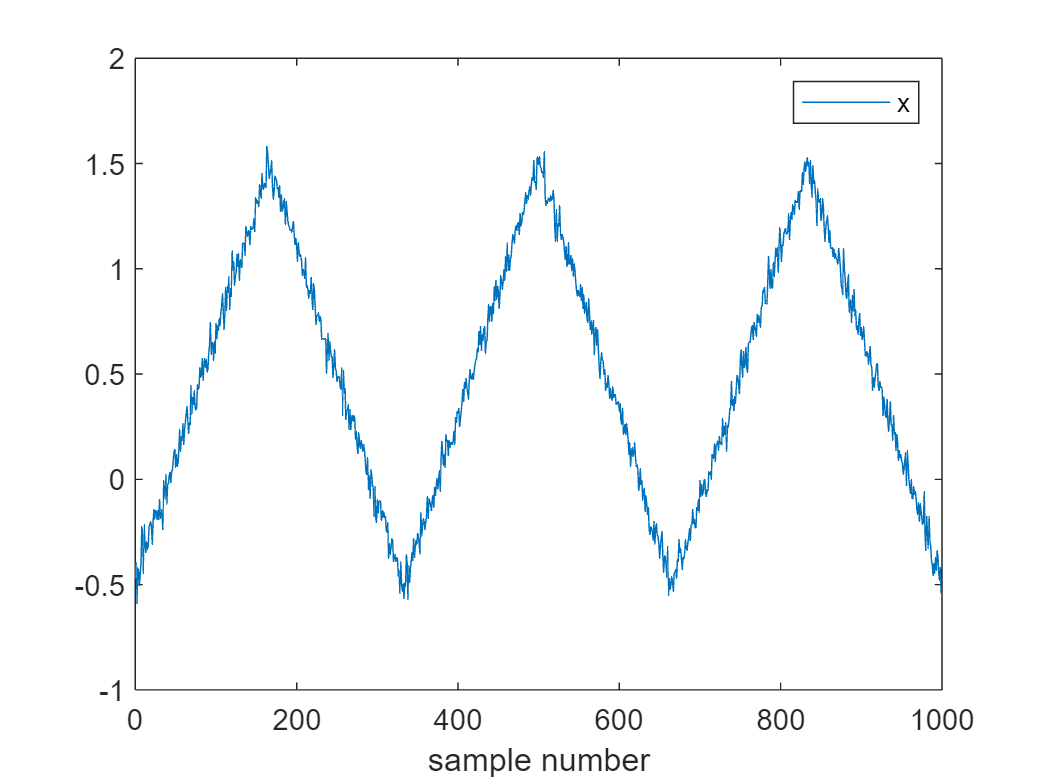

In questo esercizio sono raccolte quattro misure molto frequenti sui segnali:

- valore medio

- valore efficace

- potenza del segnale (quadrato del valore efficace)

- valor rettificato medio (media dei moduli dei campioni di segnale)

$x_{\textrm{avg}} =\frac{1}{N}\sum_{n=1}^N x_n$ valor medio

 $x_{\textrm{rms}} =\sqrt{\;\;\frac{1}{N}\sum_{n=1}^N x_n^2 }$ valore efficace

$x_{\textrm{pow}} =\frac{1}{N}\sum_{n=1}^N x_n^2$ potenza

$x_{\textrm{arv}} =\frac{1}{N}\sum_{n=1}^N \left|x_n \right|$ valor rettificato medio (average rectified value)

I coefficienti sono calcolati semplicemente per derivazione delle espressioni analitiche:


$$C_{\textrm{avg}} =\frac{1}{N}\left\lbrack 1,\cdots ,1\right\rbrack$$



$$C_{\textrm{rms}} =\frac{1}{N\;x_{\textrm{rms}} }\left\lbrack x_1 ,\cdots ,x_N \right\rbrack$$



$$C_{\textrm{pow}} =\frac{2}{N}\left\lbrack x_1 ,\cdots ,x_N \right\rbrack$$



$$C_{\textrm{arv}} =\frac{1}{N}\left\lbrack \textrm{sign}\left(x_1 \right),\cdots ,\textrm{sign}\left(x_N \right)\right\rbrack$$


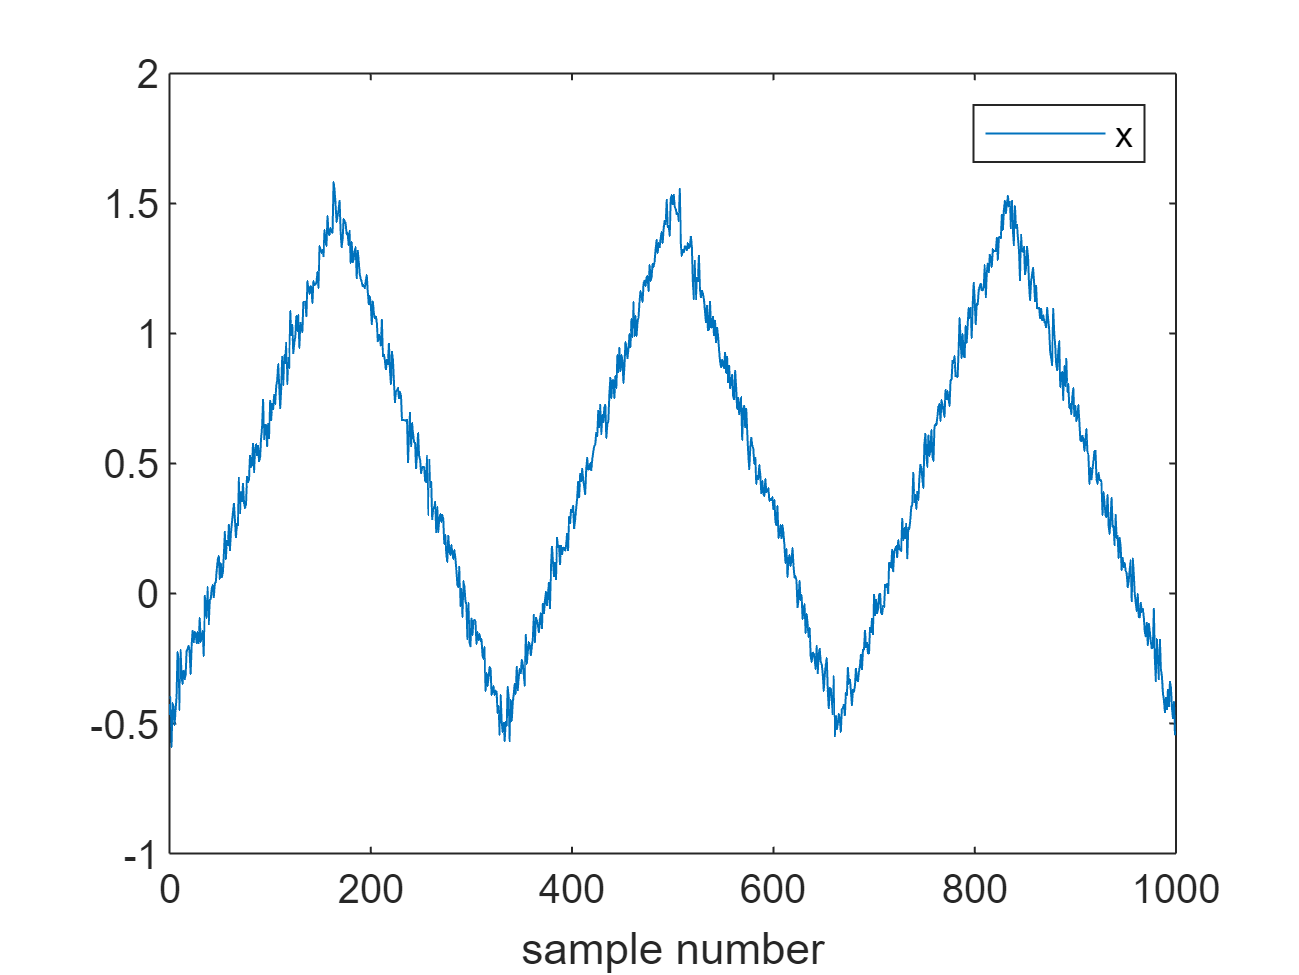

% Dati
% x = vettore colonna di campioni del segnale
% N = numero di campioni

% Domande
% x_avg = valor medio
% x_rms = valore efficace
% x_pow = potenza
% x_arv = valor medio rettificato
%
% C_avg = matrice coefficienti di sensibilità di x_avg
% C_rms = matrice coefficienti di sensibilità di x_rms
% C_pow = matrice coefficienti di sensibilità di x_pow
% C_arv = matrice coefficienti di sensibilità di x_arv

% Codice iniziale
clear
rng('default')
N = 1e3;
Np = 3;
Fx = Np/N;
n = (0:N-1)';
x = sawtooth(2*pi*Fx*n,0.5) + 0.5 + randn([N,1])*0.05;

% Grafico per figura
plot(n,x)

x_avg = 0.4984

xlabel('sample number')

x_rms = 0.7627

legend('x')

x_pow = 0.5817

x_arv = 0.6248

### Soluzione

x_avg = mean(x)
x_rms = sqrt(mean(x.^2))

C_avg = 1.0e-03 *

    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


x_pow = mean(x.^2)
x_arv = mean(abs(x))

C_rms =    -0.0006   -0.0005   -0.0008   -0.0006   -0.0006   -0.0007   -0.0006   -0.0005   -0.0003   -0.0003   -0.0006   -0.0003   -0.0004   -0.0005   -0.0004   -0.0004   -0.0004   -0.0003   -0.0003   -0.0003   -0.0003   -0.0004   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0002   -0.0003   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0000   -0.0001   -0.0001    0.0000   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001    0.0001    0.0001    0.0002    0.0002



$$C_{\textrm{avg}} =\frac{1}{N}\left\lbrack 1,\cdots ,1\right\rbrack$$


C_avg = ones(1,N)/N % riga di "1", divisa per N

C_pow =    -0.0009   -0.0008   -0.0012   -0.0008   -0.0009   -0.0010   -0.0009   -0.0008   -0.0005   -0.0005   -0.0009   -0.0004   -0.0006   -0.0007   -0.0006   -0.0007   -0.0006   -0.0004   -0.0004   -0.0004   -0.0005   -0.0006   -0.0004   -0.0003   -0.0004   -0.0003   -0.0003   -0.0004   -0.0003   -0.0004   -0.0002   -0.0004   -0.0003   -0.0003   -0.0005   -0.0000   -0.0001   -0.0002    0.0000   -0.0002   -0.0001   -0.0000    0.0000    0.0001   -0.0000    0.0001    0.0001    0.0002    0.0003    0.0003



$$C_{\textrm{rms}} =\frac{1}{N\;x_{\textrm{rms}} }\left\lbrack x_1 ,\cdots ,x_N \right\rbrack$$


C_rms = 1/(N*x_rms)*x' % attenzione: deve essere una riga, quindi si usa x' e non x

C_awg = 1.0e-03 *

   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000    1.0000   -1.0000   -1.0000   -1.0000    1.0000    1.0000   -1.0000    1.0000    1.0000    1.0000    1.0000    1.0000



$$C_{\textrm{pow}} =\frac{2}{N}\left\lbrack x_1 ,\cdots ,x_N \right\rbrack$$


C_pow = 2/N*x' % attenzione: deve essere una riga, quindi si usa x' e non x


$$C_{\textrm{arv}} =\frac{1}{N}\left\lbrack \textrm{sign}\left(x_1 \right),\cdots ,\textrm{sign}\left(x_N \right)\right\rbrack$$


C_awg = 1/N*sign(x') % attenzione: deve essere una riga, quindi si usa x' e non x

## 7 - Esempi di calcolo di modello della misurazione e di coefficienti di sensibilità

In questo esercizio sono raccolti casi tipici di calcolo di modello della misurazione e poi di coefficienti di sensibilità. Il calcolo è da eseguirsi all'esame con carta e penna (o da conoscere a memoria).

In alcuni casi è più comodo calcolare coefficienti relativi, in altri casi coefficienti assoluti. Si ricordi che esiste una formula molto semplice per passare da coefficienti relativi ad assoluti, e viceversa.

### 7.1 - Parallelo di resistenze

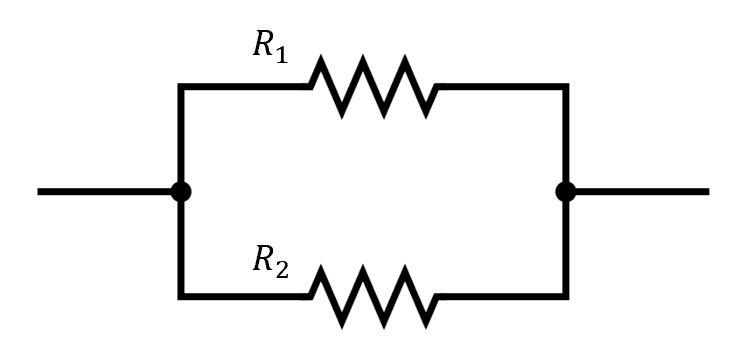

% Dati
% R1 = resistenza
% R2 = resistenza

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine R1, R2
% Rp = resistenza parallelo
% Cr = matrice dei coefficienti di sensibilità relativi di theta = Rp

% Codice iniziale
clear
R1 = 100;

x =    100
   200


R2 = 200;

Rp = 66.6667

Cr =     0.6667    0.3333


#### Soluzione

Nei coefficienti di sensibilità relativi le resistenze "pesano" in misura proporzionale al valore dell'altra. Per esempio, per $R_1 =100,R_2 =200$, i coefficienti di sensibilità sono $C_r =\left\lbrack \frac{2}{3},\frac{1}{3}\right\rbrack$

x = [R1; R2]
Rp = R1*R2/(R1+R2)

Cr = [R2/(R1+R2), R1/(R1+R2)]

### 7.2 Partitore di tensione

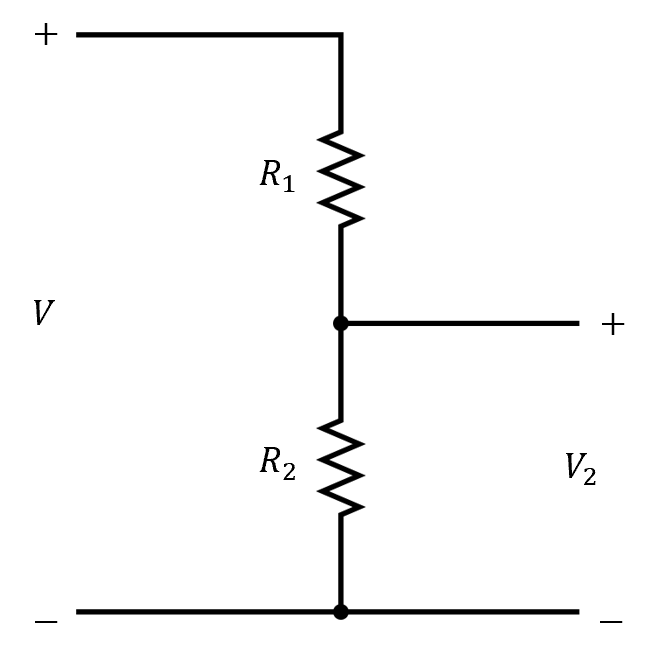

% Dati
% R1 = resistenza
% R2 = resistenza

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine R1, R2
% k = V2/V, rapporto di partizione
% Cr = matrice dei coefficienti di sensibilità relativi di theta = k

% Codice iniziale
clear
R1 = 100;

x =    100
   200


R2 = 200;

k = 0.6667

Cr =    -0.3333    0.3333


#### Soluzione

I coefficienti di sensibilità sono uguali e opposti, pari in modulo al complemento a 1 del rapporto di partizione. Per esempio, per $R_1 =100,R_2 =200$, i coefficienti di sensibilità sono $C_r =\left\lbrack -\frac{1}{3},\frac{1}{3}\right\rbrack$

x = [R1; R2]
k = R2/(R1+R2)

Cr = [-R1/(R1+R2), R1/(R1+R2)]

### 7.3 Distanza della base e della sommità di un edificio, misurate mediante triangolazione

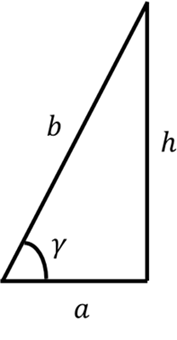

% Dati
% a = primo cateto (distanza dalla base)
% gamma = angolo in radianti

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine a, gamma
% h = secondo cateto (altezza)
% b = ipotenusa (distanza dalla sommità)
% theta = vettore colonna delle grandezze in uscita, nell'ordine h, b
% Cr = matrice dei coefficienti di sensibilità relativi di theta

% Codice iniziale
clear

x =    50.0000
    1.3090


a = 50;

h = 186.6025

gamma = 75*pi/180; % 75 gradi espresso in radianti

b = 193.1852

theta =   186.6025
  193.1852


#### Soluzione

x = [a; gamma]

Cr =     1.0000    5.2360
    1.0000    4.8852


h = a*tan(gamma)

Cr =     1.0000    5.2360
    1.0000    4.8852


b = a/cos(gamma)
theta = [h;b]

Cr = [1, gamma*(tan(gamma)^2+1)/tan(gamma); 1, gamma*tan(gamma)]
Cr = [1, gamma/(cos(gamma)^2*tan(gamma)); 1, gamma*tan(gamma)] % alternativa

### 7.4 Numero complesso: modulo e argomento calcolate da parte reale e parte immaginaria

Questo caso si presenta, ad esempio, stimando ampiezza e fase di una sinusoide col metodo OLS.

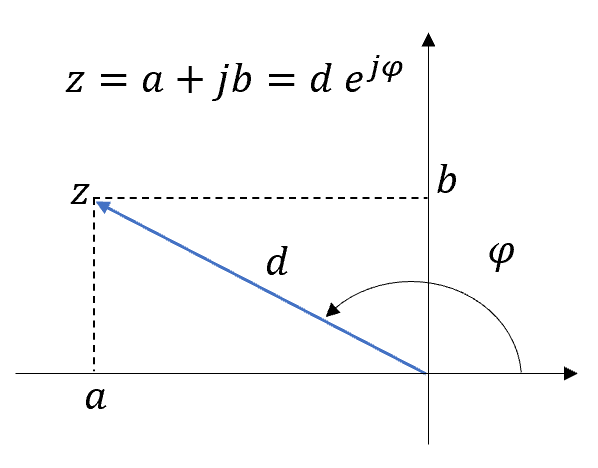

% Dati
% a = parte reale
% b = parte immaginaria

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine a, b
% d = modulo
% phi = argomento
% theta = vettore colonna delle grandezze in uscita, nell'ordine d, phi
% C = matrice dei coefficienti di sensibilità assoluti di theta

% Codice iniziale
clear

x =    -50
   100


a = -50;
b = 100;

d = 111.8034

phi = 2.0344

#### Soluzione

x = [a; b]

d = 111.8034

phi = 2.0344

d = sqrt(a^2+b^2)
phi = atan2(b,a)

theta =   111.8034
    2.0344


d = abs(a+1j*b) % alternativa

C =    -0.4472    0.8944
   -0.0080   -0.0040


phi = angle(a+1j*b) % alternativa

theta = [d; phi]

C = [a/d, b/d; -b/d^2, a/d^2]

### 7.5 Numero complesso: parte reale e parte immaginaria calcolate da modulo e argomento

E' il problema inverso del precedente. In questo caso calcoliamo sia $C$ che $C_r$ (sono entrambi calcoli molto facili)

% Dati
% d = modulo
% phi = argomento

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine d, phi
% a = parte reale
% b = parte immaginaria
% theta = vettore colonna delle grandezze in uscita, nell'ordine a, b
% C = matrice dei coefficienti di sensibilità assoluti di theta
% Cr = matrice dei coefficienti di sensibilità relativi di theta

% Codice iniziale
clear

x =   100.0000
    2.6180


d = 100;
phi = 5/6*pi;

a = -86.6025

b = 50.0000

#### Soluzione

x = [d; phi]

a = -86.6025

b = 50.0000

a = d*cos(phi)
b = d*sin(phi)

theta =   -86.6025
   50.0000


a = real(d*exp(1j*phi)) % alternativa

C =    -0.8660  -50.0000
    0.5000  -86.6025


b = imag(d*exp(1j*phi)) % alternativa

Cr =     1.0000    1.5115
    1.0000   -4.5345


theta = [a; b]

Cr =     1.0000    1.5115
    1.0000   -4.5345


C = [cos(phi), -d*sin(phi); sin(phi), d*cos(phi)]

Cr = [1, -phi*tan(phi); 1, phi/tan(phi)]

Cr = C./theta.*x' % verifica

### 7.6 Rapporto di valori picco-picco

E' un caso che si presenta spesso in pratica, anche se di solito per calcolare l'incertezza di questa misura vanno applicate le specifiche dell'oscilloscopio.

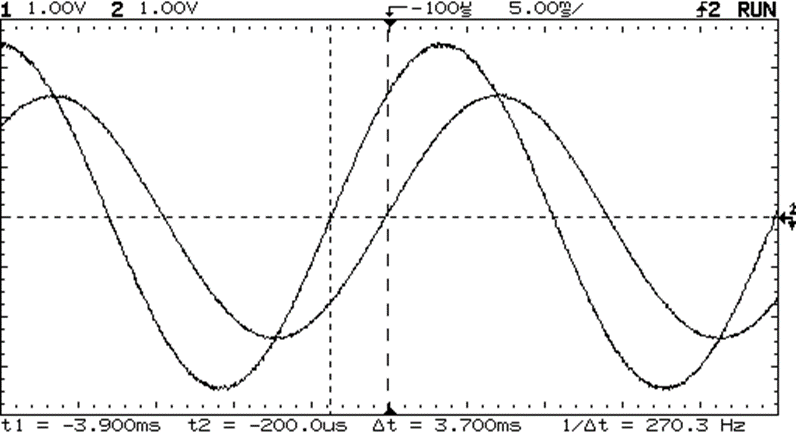

% Dati
% V1 = valore massimo tensione in uscita
% V2 = valore minimo tensione in uscita
% V3 = valore massimo tensione in ingresso
% V4 = valore minimo tensione in ingresso

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine V1, V2, V3, V4
% H = rapporto tra valori picco-picco in uscita e in ingresso
% Cr = matrice dei coefficienti di sensibilità relativi di H

% Codice iniziale
clear

x =     10
    -8
     5
    -3


V1 = 10; V2 = -8;
V3 = 5; V4 = -3;

Vpp_out = 18

Vpp_in = 8

H = 2.2500

#### Soluzione

x = [V1; V2; V3; V4]

Cr =     0.5556    0.4444   -0.6250   -0.3750


Vpp_out = V1-V2
Vpp_in = V3-V4
H = Vpp_out/Vpp_in

Cr = [V1/Vpp_out, -V2/Vpp_out, -V3/Vpp_in, V4/Vpp_in]

ans = 0

ans = 0

Nota:

La somma dei coefficienti relativi di sensibilità è sempre 0.

Anche la somma dei coefficienti divisi ognuno per la variabile a cui si riferisce è 0:$\frac{C_{r,1} }{V_1 }+\frac{C_{r,2} }{V_2 }+\frac{C_{r,3} }{V_3 }+\frac{C_{r,4} }{V_4 }=0$

sum(Cr)
sum(Cr./x')